# Case study of SF downtown

effects of collapse cordon

## City view

### 3D view

global filename
filename = '../input data/BuildingData/SanFrancisco_buildings_partial.csv';
facecolor = [0.4660 0.6740 0.1880]; % green
facealpha = 0.5;
plot_bld_3D(filename,facecolor,facealpha);

### 2D view

Note that some very close buildings share the same footprint (maybe it's because it's too diffucult to distinguish them only by satelite images), so their footprints have darker colors than others due to overlaps. However, these buildings actually have different other information, like plan areas and structural types, which are obtained based on field survey.

alpha = 0.5;
plot_bld_story(filename)
% plot_bld(filename,[0.4660 0.6740 0.1880],alpha);

## Earthquake & Loss Simulation

### Earthquake simulation

EQ point source is defined in EQSource.txt. Earthquake intensities are simulated on grid points.

### Loss simulation

Loss simulation results are saved in ’input data\LossSimResults’

Read total results. 

global OutputDir
OutputDir = '../input data/LossSimResults';
[TotalLossSimResults,InvalidBldID]  = ReadLossSimResults(filename,OutputDir);

Plot CDF of losses: repair time

samples = plot_cdf_regional(TotalLossSimResults,{'RepairTime','RecoveryTime','FunctionLossTime'});

Plot CDF of losses: repair cost

samples = plot_cdf_regional(TotalLossSimResults,{ ...
    'RepairCost_Total','RepairCost_Struct','RepairCost_NonStruct_DriftSen', 'RepairCost_NonStruct_AccelSen'});

Damage states

Type = 'DS_Struct';
plot_bld_DS(filename,OutputDir,Type);

## Recovery simulation

### Simulation

Parameters

global Nsim
Nsim = 50;
RTbeta = 0.2; % Repair time uncertainty. Beta of lognormal distribution

Initial damage states & maximum damage states. 

4 functional states are defined: unsafe, safe (but not functional), functional, normal.

% FS: Nsim x N int matrix; IRTsCell: Nsim x N cell
[FS,IRTsCell] = ReadFS(filename,OutputDir,Nsim,RTbeta); 
MS = 4.*ones(1,size(FS,2));

Dependency relationships

Rhr = 1.5;
hmin = 10;
Dep = DetermineDep(filename,Rhr,hmin); % kx4 matrix
Dep_None = []; % independent

Recovery time step parameters

DeltaT_range = [1,5/4,5/3,5/2].*10;
MaxT = 1500;

t: simulation time cost. Average time for each time of simualtion. 

F_t: Function-time trajectories

F_t = [];
t = [];

Independent

for it = 1:numel(DeltaT_range)
    DeltaT = DeltaT_range(it);
    [t.indep.asy(it),F_t.indep.asy{it}] = TicTocRecoverySimAsy(Dep_None,FS,MS,IRTsCell);
    [t.indep.syn(it),F_t.indep.syn{it}] = TicTocRecoverySimSyn(Dep_None,FS,MS,IRTsCell,DeltaT,MaxT);
end

Interdependent

for it = 1:numel(DeltaT_range)
    DeltaT = DeltaT_range(it);
    [t.interdep.asy(it),F_t.interdep.asy{it}] = TicTocRecoverySimAsy(Dep,FS,MS,IRTsCell);
    [t.interdep.syn(it),F_t.interdep.syn{it}] = TicTocRecoverySimSyn(Dep,FS,MS,IRTsCell,DeltaT,MaxT);
end

### Plot results

#### Figure: function recovery curves

Parameters

iDeltaT = 1;
FunctionState = 3;

Code

xq = 0:1:1500;
for i = ["indep","interdep"]
    for j=["syn","asy"]
        figure
        hold on
        temp = [];
        for ieq = 1:Nsim
            xy = F_t.(i).(j){iDeltaT}{ieq};
            x = xy(FunctionState*2-1,:);
            y = xy(FunctionState*2,:);
            plot(x,y,Color=[0.6 0.6 0.6]);
            % mean data
            xnew = x;
            Nsame = 0;
            for ix = 2:numel(x)
                if x(ix)==x(ix-1)
                    Nsame = Nsame+1;
                    xnew(ix) = x(ix)+0.001*Nsame;
                else
                    Nsame = 0;
                end
            end
            temp = [temp;interp1(xnew,y,xq,'nearest','extrap')];
        end
        plot(xq,mean(temp,1),Color=[0.6350 0.0780 0.1840],LineWidth=2);

        % placeholder
        ph = [];
        ph(1) = plot([0,0],Color=[0.6350 0.0780 0.1840],LineWidth=2);
        ph(2) = plot([0,0],Color=[0.6 0.6 0.6]);
        legend(ph,{'Mean','Individual'},'Location','southeast')

        box on;
        % grid on;
        xlabel('$\mathrm{Time\ (days)}$','Interpreter','latex');
        ylabel('$\mathrm{Function}$','Interpreter','latex');
        % title(['$S_{a,y}=',num2str(IM_1),'\ \mathrm{g},\ T=', , ...
        %     '$'],'Interpreter','latex');
        ax = gca; 
        ax.FontSize = 12;
        ax.FontName = 'Times new roman';
        ax.TickLength = [0.02 0.035].*1.5;
        % ylim([0 1]);
        set(gcf,'Units','centimeters');
        set(gcf,'Position',[5 5 6 5]);
        % title(strcat(i,', ',j));
        xlim([0 1500])
    end
end

Average recovey curves

figure
hold on
xq = 0:1:1500;
for i = ["indep","interdep"]
    for j=["syn","asy"]
        temp = [];
        for ieq = 1:Nsim
            xy = F_t.(i).(j){iDeltaT}{ieq};
            x = xy(FunctionState*2-1,:);
            y = xy(FunctionState*2,:);
            xnew = x;
            Nsame = 0;
            for ix = 2:numel(x)
                if x(ix)==x(ix-1)
                    Nsame = Nsame+1;
                    xnew(ix) = x(ix)+0.001*Nsame;
                else
                    Nsame = 0;
                end
            end
            temp = [temp;interp1(xnew,y,xq,'nearest','extrap')];
        end
        p = plot(xq,mean(temp,1),LineWidth=1.5);
        if strcmp(j,"syn")
            p.Color = [0.6350 0.0780 0.1840];
            if strcmp(i,"indep")
                p.LineStyle = '--';
            else
                p.LineStyle = ':';
            end
        else
            p.Color = [0 0.4470 0.7410];
            p.LineWidth = 1;
            if strcmp(i,"indep")
                p.LineStyle = '--';
            end
        end
        
    end
end
lgd = {'Ind., Syn.', 'Ind., Asyn.', 'Interdep., Syn.', 'Interdep., Asyn.'};

box on;
% grid on;
xlabel('$\mathrm{Time\ (days)}$','Interpreter','latex');
ylabel('$\mathrm{Function}$','Interpreter','latex');
% title(['$S_{a,y}=',num2str(IM_1),'\ \mathrm{g},\ T=', , ...
%     '$'],'Interpreter','latex');
ax = gca; 
ax.FontSize = 12;
ax.FontName = 'Times new roman';
ax.TickLength = [0.02 0.035].*1.5;
% ylim([0 1]);
set(gcf,'Units','centimeters');
set(gcf,'Position',[5 5 6 5]);
legend(lgd,Location="southeast",FontSize=9);

#### Figure: computer time VS Number of buildings

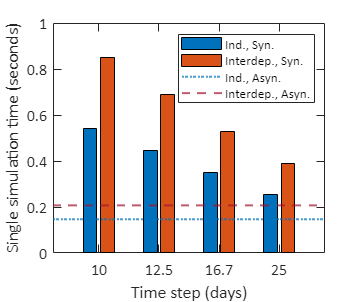

figure
hold on
y = []; % deltaT, Syn, interdep
IndORDep = ["indep","interdep"];
SynORAsy = ["syn","asy"];
for i = 1:numel(IndORDep)
    for j=1:1
        for it = 1:numel(DeltaT_range)
            y(it,j,i) = t.(IndORDep(i)).(SynORAsy(j))(it);
        end
    end
end
X = categorical(string(round(DeltaT_range,1)));
X = reordercats(X,string(round(DeltaT_range,1)));
b = bar(X,reshape(y,numel(DeltaT_range),[]));
% b.FaceColor = 'flat';
b(1).CData = [0 0.4470 0.7410];
b(2).CData = [0.6350 0.0780 0.1840];

% plot asyn
yline(mean(t.indep.asy),Color=[0 0.4470 0.7410],LineStyle=':',LineWidth=1.5);
yline(mean(t.interdep.asy),Color=[0.6350 0.0780 0.1840],LineStyle='--',LineWidth=1.5);

box on;
% grid on;
xlabel('Time step (days)');
ylabel('Single simulation time (seconds)');
% title(['$S_{a,y}=',num2str(IM_1),'\ \mathrm{g},\ T=', , ...
%     '$'],'Interpreter','latex');
ax = gca; 
ax.FontSize = 12;
ax.FontName = 'Calibri';
ax.TickLength = [0.02 0.035].*1.5;
% ylim([0 1]);
set(gcf,'Units','centimeters');
set(gcf,'Position',[5 5 9.5 8]);
lgd = {'Ind., Syn.','Interdep., Syn.','Ind., Asyn.','Interdep., Asyn.'};
legend(lgd,Location="northeast",FontSize=10);

#### Figure: functional states at any time

Parameters

isim = 1;

Code

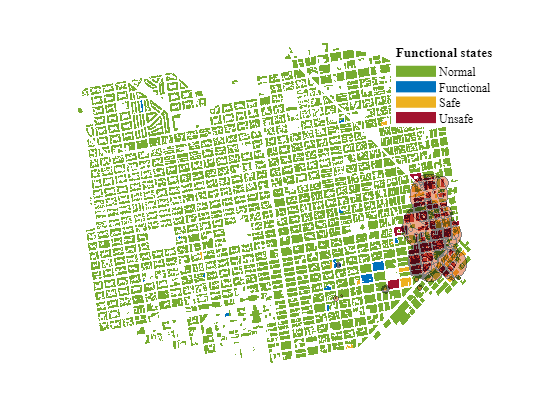

[T,~,~,Dnew] = AsyRecovSim(Dep,MS,FS(isim,:),IRTsCell(isim,:)); % one simulation
t = 1500;
plot_bld_FS_cordon(filename,T,t,Rhr,Dnew);